# Setup

% Add paths for SDETools
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\SDETools'

% Default Parameters
dt = 0.02; 
tmax = 10000;
t = 0:dt:tmax;   
N = 100;
h = 0.1;                     
theta = 6;
sig = 1;

Heterophily

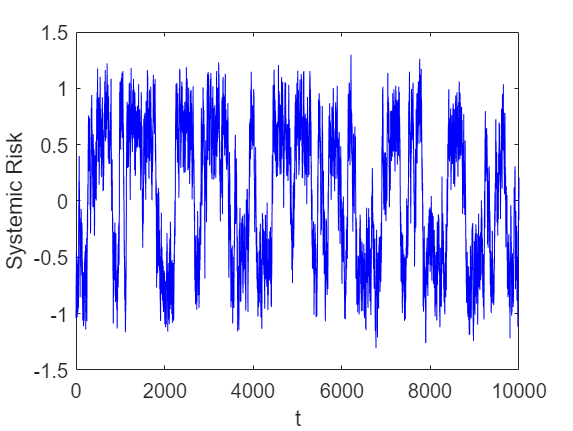

threshold = 1;
x = SolveSDE(t, N, h, sig, theta, @(x) heterophily(x, threshold));
PlotSDE(t, x);

Homophily

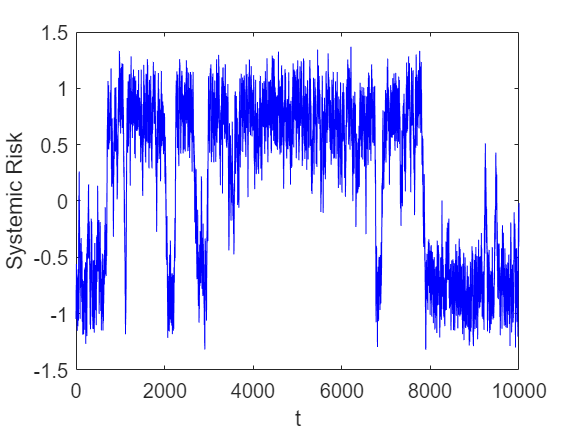

x = SolveSDE(t, N, h, sig, theta, @(x) homophily(x, threshold));
PlotSDE(t, x);

Disconnected/Bipartite

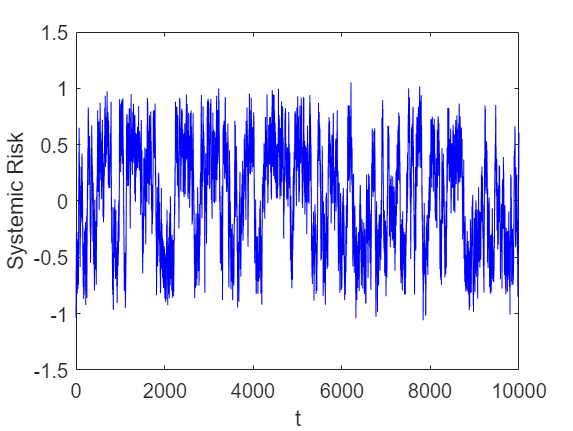

x = SolveSDE(t, N, h, sig, theta, @(x) bipartite(x));

PlotSDE(t, x);

Connected

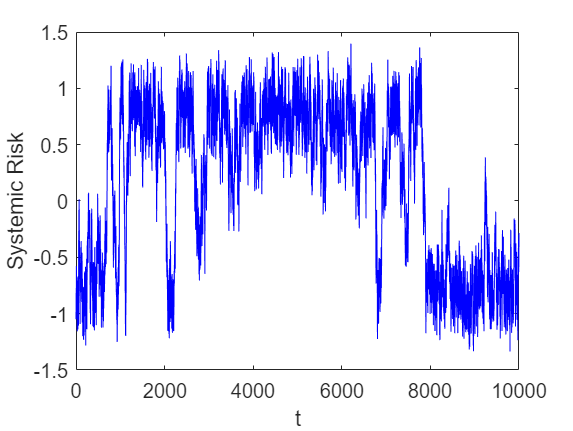

x = SolveSDE(t, N, h, sig, theta, @(x) connected(x));
PlotSDE(t, x);

Erdos-Renyi

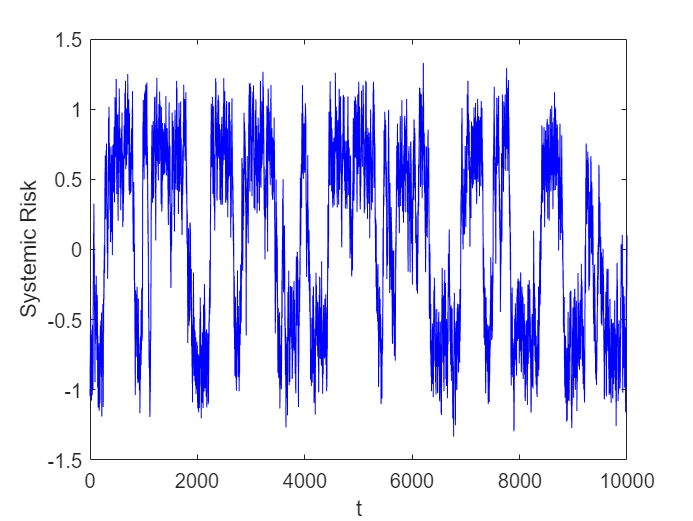

x = SolveSDE(t, N, h, sig, theta, @(x) ErdosRenyi(x, 0.5));
PlotSDE(t, x);

Random graph (with p = 0.1)

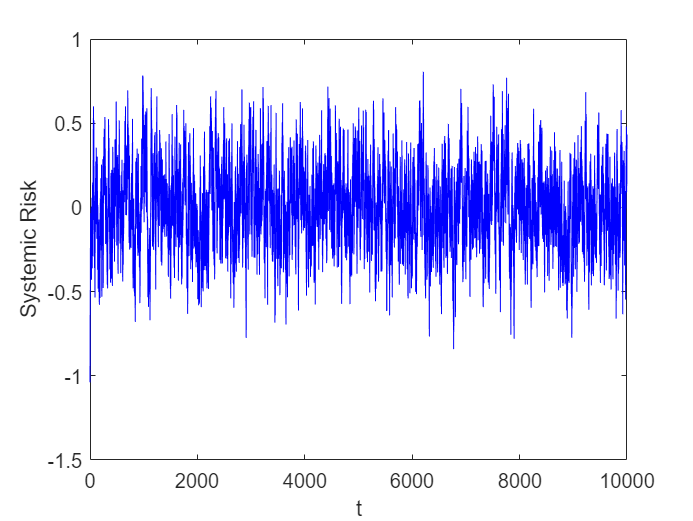

x = SolveSDE(t, N, h, sig, theta, @(x) ErdosRenyi(x, 0.1));
PlotSDE(t, x);

Random graph (with p = 0.3)

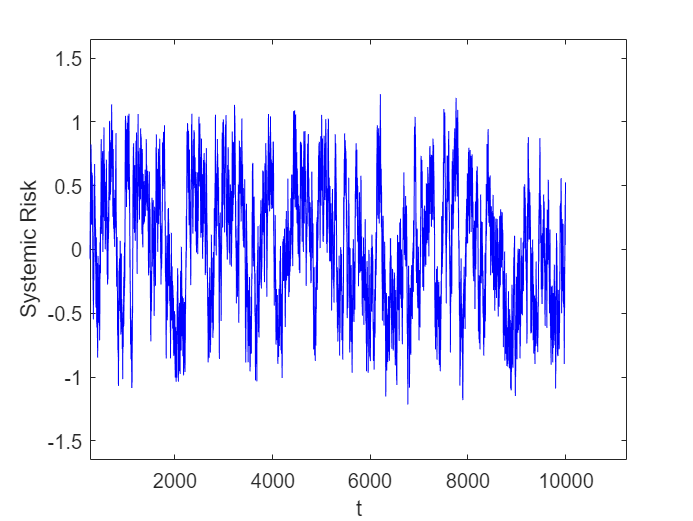

x = SolveSDE(t, N, h, sig, theta, @(x) ErdosRenyi(x, 0.3));
PlotSDE(t, x);